% process data
filename = "Push\Push_1.mat"

filename = "Push\Push_1.mat"

[MotionData]=ParseMatlabApp(filename);
t = MotionData.t_Accel; 
accel = MotionData.Accel;

secondsToTrim = 5;
[t, accel] = trim_accel_data(t, accel, secondsToTrim);

Fs = 50;    
reduction_range = 0.1;
ax = reduce_gravity(moving_avg(accel(:,1)), Fs, reduction_range);
ay = reduce_gravity(moving_avg(accel(:,2)), Fs, reduction_range);
az = reduce_gravity(moving_avg(accel(:,3)), Fs, reduction_range);

N = size(accel);
N = N(1);
f = linspace(-Fs/2 , Fs/2 - Fs/N, N) + Fs/(2*N)*mod(N,2);

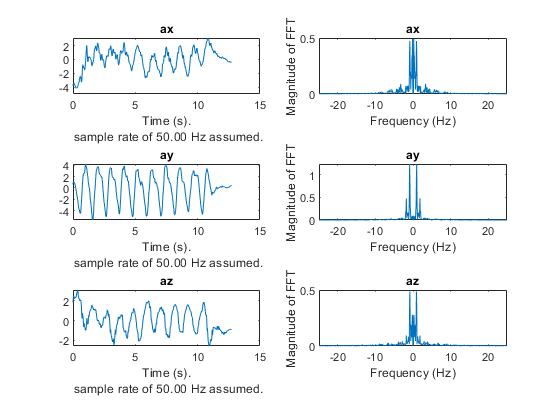

figure
hold on
subplot(3,2,1)

make_time_plot(ax, Fs, 'ax')
subplot(3,2,2)
make_freq_plot(ax, Fs, 'ax')

subplot(3,2,3)
make_time_plot(ay, Fs, 'ay')
subplot(3,2,4)
make_freq_plot(ay, Fs, 'ay')

subplot(3,2,5)
make_time_plot(az, Fs, 'az')
subplot(3,2,6)
make_freq_plot(az, Fs, 'az')
hold off

% get frequency domain variables:
[ax_freq, ax_amp] = get_freq_domain_variables(ax, Fs);
[ay_freq, ay_amp] = get_freq_domain_variables(ay, Fs);
[az_freq, az_amp] = get_freq_domain_variables(az, Fs);

% % find max of ax, ay, az:
ax_max = max(ax_amp)

ax_max = 0.4925

ay_max = max(ay_amp)

ay_max = 1.2317

az_max = max(az_amp)

az_max = 0.4879

% ax_max
% ay_max

% [max_ax_i, max_ax] = max(ax)
% [max_ay_i, max_ay] = max(ay)
% [max_az_i, max_az] = max(az)

% if max.ax > 0.5:
% (Y) is max.AY > 0.25 or (N) is max.AZ > 0.6



